# Exam 12 June 2023

## ex3

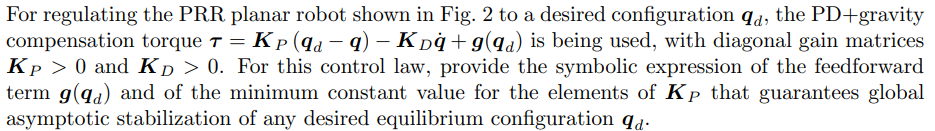

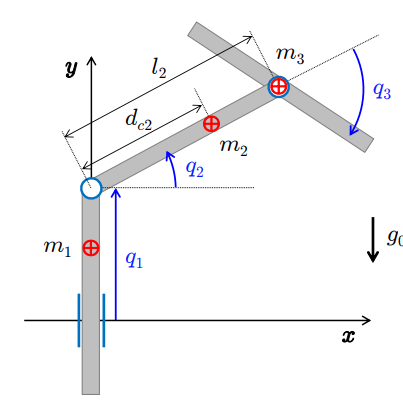

syms q1 q2 q3 q_dot_1 q_dot_2 q_dot_3 real
syms d_1 d_2 d_3 m_1 m_2 m_3 I_1 I_2 I_3 g0 l_2 positive

U1 = m_1*g0*q1

$$U1 = g_{0}\,m_{1}\,q_{1}$$

U2 = m_2*g0*(q1+d_2*sin(q2))

$$U2 = g_{0}\,m_{2}\,\left(q_{1}+d_{2}\,\sin\left(q_{2}\right)\right)$$

U3 = m_3*g0*(q1+l_2*sin(q2))

$$U3 = g_{0}\,m_{3}\,\left(q_{1}+l_{2}\,\sin\left(q_{2}\right)\right)$$


U = [U1+U2+U3];
g_q = simplify([diff(U,q1); diff(U,q2); diff(U,q3)], Steps=100)

$$g\_q = \left(\begin{array}{c} g_{0}\,\left(m_{1}+m_{2}+m_{3}\right)\\ g_{0}\,\cos\left(q_{2}\right)\,\left(d_{2}\,m_{2}+l_{2}\,m_{3}\right)\\ 0 \end{array}\right)$$

g_q_dot = jacobian(g_q,[q1,q2,q3])

$$g\_q\_dot = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & -g_{0}\,\sin\left(q_{2}\right)\,\left(d_{2}\,m_{2}+l_{2}\,m_{3}\right) & 0\\ 0 & 0 & 0 \end{array}\right)$$


eigen_g_q_dot = simplify(eig(g_q_dot))

$$eigen\_g\_q\_dot = \left(\begin{array}{c} 0\\ 0\\ -g_{0}\,\sin\left(q_{2}\right)\,\left(d_{2}\,m_{2}+l_{2}\,m_{3}\right) \end{array}\right)$$

## ex4

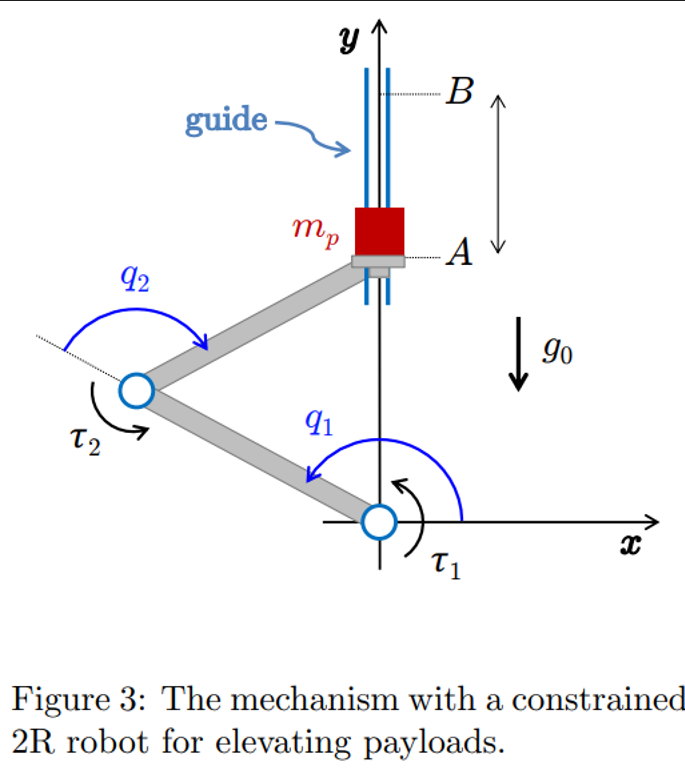

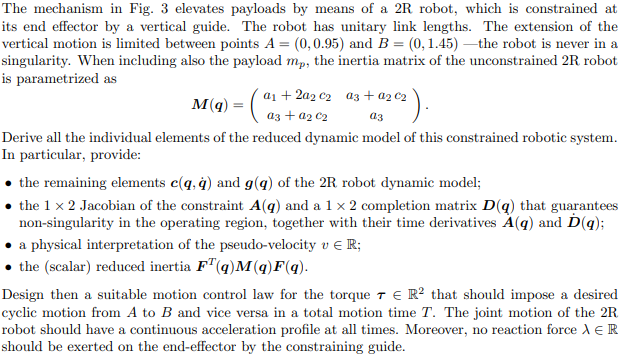

### Point 1

syms q1 q2 q_dot_1 q_dot_2 a_1 a_2 a_3 x_A x_B y_A y_B real
syms m_1 m_2 d_1 d_2 l_1 l_2 g0 m_p positive

% Inertia Matrix
M = [a_1+2*a_2*cos(q2) a_3+a_2*cos(q2);
     a_3+a_2*cos(q2) a_3;];

% Gravity Terms
U1 = m_1*g0*(d_1*sin(q1))

$$U1 = d_{1}\,g_{0}\,m_{1}\,\sin\left(q_{1}\right)$$

U2 = m_2*g0*(sin(q1)+d_2*sin(q1+q2))

$$U2 = g_{0}\,m_{2}\,\left(\sin\left(q_{1}\right)+d_{2}\,\sin\left(q_{1}+q_{2}\right)\right)$$

Up = m_p*g0*(sin(q1)+sin(q1+q2))

$$Up = g_{0}\,m_{p}\,\left(\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\right)$$


U = [U1+U2+Up];
g_q = simplify([diff(U,q1); diff(U,q2);], Steps=100)

$$g\_q = \left(\begin{array}{c} g_{0}\,m_{p}\,\left(\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\right)+g_{0}\,m_{2}\,\left(\cos\left(q_{1}\right)+d_{2}\,\cos\left(q_{1}+q_{2}\right)\right)+d_{1}\,g_{0}\,m_{1}\,\cos\left(q_{1}\right)\\ g_{0}\,\cos\left(q_{1}+q_{2}\right)\,\left(m_{p}+d_{2}\,m_{2}\right) \end{array}\right)$$


% Coriolis and Centrifugal force
q  = [q1; q2;];
dq = [q_dot_1; q_dot_2;];
C = sym(zeros(2,2));

for i = 1:2
    for j = 1:2
        tmp = 0;
        for k = 1:2
            tmp = tmp + 0.5 * ( ...
                diff(M(i,j), q(k)) + ...
                diff(M(i,k), q(j)) - ...
                diff(M(k,j), q(i)) ) * dq(k);
        end
        C(i,j) = simplify(tmp); 
    end
end

c_vec = simplify(C * dq);
disp('La matrice di Coriolis C(q,dq) è:');

La matrice di Coriolis C(q,dq) è:


disp(C);

$$\left(\begin{array}{cc} -a_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right) & -a_{2}\,\sin\left(q_{2}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)\\ a_{2}\,{\dot{q}}_{1}\,\sin\left(q_{2}\right) & 0 \end{array}\right)$$


disp('Il vettore c(q,dq) = C(q,dq)*dq è:');

Il vettore c(q,dq) = C(q,dq)*dq è:


disp(c_vec);

$$\left(\begin{array}{c} -a_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\,\left(2\,{\dot{q}}_{1}+{\dot{q}}_{2}\right)\\ a_{2}\,{{\dot{q}}_{1}}^{2}\,\sin\left(q_{2}\right) \end{array}\right)$$

### Point 2

r = [cos(q1)+cos(q1+q2); 
     sin(q1)+sin(q1+q2);];
% !IMPORTANTE il moto è solo verticale x_A = x_B = 0 e x = 0!
h_q = [(cos(q1)+cos(q1+q2)-x_A)*(y_B-y_A)-(sin(q1)+sin(q1+q2)-y_A)*(x_B-x_A);];
h_q_subs = subs(h_q,[x_A,x_B],[0,0])

$$h\_q\_subs = -\left(y_{A}-y_{B}\right)\,\left(\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\right)$$

A = jacobian(h_q_subs,[q1,q2])

$$A = \left(\begin{array}{cc} \left(y_{A}-y_{B}\right)\,\left(\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\right) & \sin\left(q_{1}+q_{2}\right)\,\left(y_{A}-y_{B}\right) \end{array}\right)$$

null_A = simplify(null(A))

$$null\_A = \left(\begin{array}{c} -\frac{\sin\left(q_{1}+q_{2}\right)}{\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)}\\ 1 \end{array}\right)$$

D = null_A.'

$$D = \left(\begin{array}{cc} -\frac{\sin\left(q_{1}+q_{2}\right)}{\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)} & 1 \end{array}\right)$$


% Check for singularities
A_D = [A; null_A.';];
det_A_D = simplify(det(A_D),steps=1000)

$$det\_A\_D = 2\,\sin\left(q_{1}+q_{2}\right)\,\left(y_{A}-y_{B}\right)+\frac{{\sin\left(q_{1}\right)}^{2}\,\left(y_{A}-y_{B}\right)}{\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)}$$

singularities = solve(det_A_D == 0, [q1, q2], 'Real', true)

singularities = struct with fields:
    q1: [0×1 sym]
    q2: [0×1 sym]



q = [q1; q2];
dq = [q_dot_1; q_dot_2];
% Prealloca vettore per dotA
dotA = sym(zeros(size(A)));

% Applica regola della catena: dA/dt = ∂A/∂q * dq
for i = 1:length(q)
    dotA = dotA + diff(A, q(i)) * dq(i);
end
dotA = simplify(dotA,steps=1000)

$$dotA = \left(\begin{array}{cc} {\dot{q}}_{2}\,\cos\left(q_{1}+q_{2}\right)\,\left(y_{A}-y_{B}\right)+{\dot{q}}_{1}\,\left(y_{A}-y_{B}\right)\,\left(\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\right) & \cos\left(q_{1}+q_{2}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)\,\left(y_{A}-y_{B}\right) \end{array}\right)$$


dotD = sym(zeros(size(D)));
for i = 1:length(q)
    dotD = dotD + diff(D, q(i)) * dq(i);
end
dotD = simplify(dotD,steps=1000)

$$dotD = \left(\begin{array}{cc} \frac{2\,{\dot{q}}_{1}\,\sin\left(q_{2}\right)+{\dot{q}}_{2}\,\sin\left(q_{2}\right)-{\dot{q}}_{2}\,\sin\left(2\,q_{1}+q_{2}\right)}{2\,\left(2\,{\sin\left(q_{1}+\frac{q_{2}}{2}\right)}^{2}-2\,{\sin\left(\frac{q_{2}}{2}\right)}^{2}+{\sin\left(q_{1}+q_{2}\right)}^{2}+{\sin\left(q_{1}\right)}^{2}\right)} & 0 \end{array}\right)$$

### Point 3

v = simplify(D*[q_dot_1; q_dot_2;])

$$v = {\dot{q}}_{2}-\frac{{\dot{q}}_{1}\,\sin\left(q_{1}+q_{2}\right)}{\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)}$$

% Check
y = r(2)

$$y = \sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)$$

y_dot = diff(y,q1)*q_dot_1+diff(y,q2)*q_dot_2

$$y\_dot = {\dot{q}}_{2}\,\cos\left(q_{1}+q_{2}\right)+{\dot{q}}_{1}\,\left(\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\right)$$

check = simplify(y_dot - v, steps=1000) % da chiedere a De luca

$$check = {\dot{q}}_{2}\,\cos\left(q_{1}+q_{2}\right)-{\dot{q}}_{2}+{\dot{q}}_{1}\,\left(\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\right)+\frac{{\dot{q}}_{1}\,\sin\left(q_{1}+q_{2}\right)}{\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)}$$

### Point 4

inv_A_D = simplify(inv(A_D),steps=1000)

$$inv\_A\_D = \begin{array}{l} \left(\begin{array}{cc} \frac{\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)}{\left(y_{A}-y_{B}\right)\,\sigma_{1}} & \frac{{\sin\left(q_{1}\right)}^{2}}{2\,\sigma_{1}}-\frac{1}{2}\\ \frac{\sin\left(q_{1}+q_{2}\right)}{\left(y_{A}-y_{B}\right)\,\sigma_{1}} & \frac{{\left(\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\right)}^{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,{\sin\left(q_{1}+q_{2}\right)}^{2}+2\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{1}\right)+{\sin\left(q_{1}\right)}^{2} \end{array}$$

F = simplify(inv_A_D(:,2))

$$F = \begin{array}{l} \left(\begin{array}{c} \frac{{\sin\left(q_{1}\right)}^{2}}{2\,\sigma_{1}}-\frac{1}{2}\\ \frac{{\left(\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\right)}^{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,{\sin\left(q_{1}+q_{2}\right)}^{2}+2\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{1}\right)+{\sin\left(q_{1}\right)}^{2} \end{array}$$

scalar = simplify(F.'*M*F, steps=1000)

$$scalar = \begin{array}{l} \frac{{\left(\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\right)}^{2}\,\left(a_{3}\,{\sin\left(q_{1}\right)}^{2}+a_{1}\,\sigma_{1}-a_{3}\,\sigma_{1}-2\,a_{2}\,\sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\right)}{{\left(2\,\sigma_{1}+2\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{1}\right)+{\sin\left(q_{1}\right)}^{2}\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}={\sin\left(q_{1}+q_{2}\right)}^{2} \end{array}$$


% % --- Definizione delle variabili simboliche ---
% syms q1 q2 real; % Angoli dei giunti
% syms l1 l2 real; % Lunghezze dei link (verranno sostituite)
% 
% % --- Parametri specifici dell'esercizio ---
% % Dall'immagine dell'esercizio (image_3c68c8.png, Figure 3) e la menzione
% % di "unitary link lengths", assumiamo l1=1, l2=1.
% % La guida verticale è sull'asse y, quindi la coordinata x dell'end-effector è 0.
% l1_val = 1;
% l2_val = 1;
% 
% % --- 1. Definizione della funzione di vincolo h(q) ---
% % Il vincolo è che la coordinata x dell'end-effector sia zero:
% % x_e = l1*cos(q1) + l2*cos(q1+q2) = 0
% % Quindi, h(q) = l1*cos(q1) + l2*cos(q1+q2)
% h = l1_val * cos(q1) + l2_val * cos(q1 + q2);
% 
% fprintf('Funzione di vincolo h(q):\n');
% disp(h);
% 
% % --- 2. Calcolo della Jacobiana del vincolo A(q) ---
% % A(q) = dh/dq. È una matrice 1x2 poiché c'è 1 vincolo e 2 giunti.
% q_vec = [q1; q2];
% A_q = jacobian(h, q_vec);
% 
% fprintf('\nJacobiana del vincolo A(q) = dh/dq:\n');
% disp(A_q);
% 
% % --- 3. Determinazione di una base F(q) per lo spazio nullo di A(q) ---
% % A(q) è una matrice 1x2. Se A_q = [a b], un vettore nello spazio nullo è [-b; a].
% % Questo vettore F(q) sarà 2x1. Le sue colonne formano una base per le velocità
% % dei giunti che soddisfano il vincolo (A(q)*F(q) = 0).
% % A_q(1) è il primo elemento di A_q, A_q(2) è il secondo.
% F_q = [-A_q(2); A_q(1)];
% 
% fprintf('\nBase F(q) per lo spazio nullo di A(q) (tale che A(q)*F(q)=0):\n');
% disp(F_q);
% 
% % Verifica che A(q)*F(q) = 0
% check_AF = simplify(A_q * F_q);
% fprintf('\nVerifica A(q)*F(q) (dovrebbe essere 0):\n');
% disp(check_AF); % Dovrebbe risultare [0]
% 
% % --- 4. Calcolo della matrice di completamento D(q) usando pseudoinversa ---
% % Costruisco la matrice Y composta da A(q) e F(q)^T come righe
% Y = [A_q; F_q.']; % 2x2 matrice
% 
% % Calcolo D(q) come la seconda riga della pseudoinversa di Y
% Y_pinv = simplify(inv(Y.' * Y) * Y.'); % pseudoinversa di Y
% D_q = Y_pinv( :, 2 ).'; % D(q) è la riga corrispondente a F(q)
% 
% fprintf('\nMatrice di completamento D(q) calcolata come pseudoinversa:\n');
% disp(simplify(D_q,steps=1000));
% 
% % Verifica che A(q)*F(q) = 0 e D(q)*F(q) = 1
% check_AF = simplify(A_q * F_q);
% check_DF = simplify(D_q * F_q);
% 
% fprintf('\nVerifica A(q)*F(q) (dovrebbe essere 0):\n');
% disp(check_AF);
% 
% fprintf('\nVerifica D(q)*F(q) (dovrebbe essere 1):\n');
% disp(check_DF);